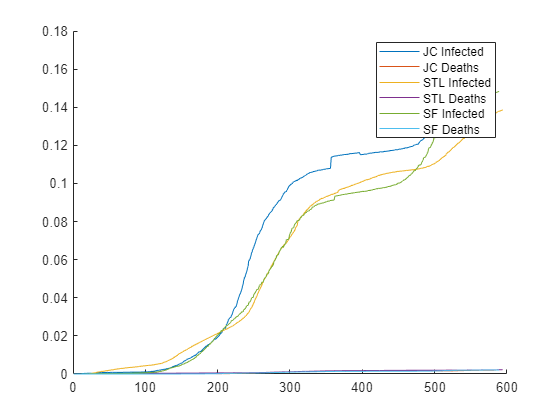

% Here is an example that reads in infection and fatalities from STL City
% and loads them into a new matrix covidstlcity_full
% In addition to this, you have other matrices for the other two regions in question
% DEBUG
base_data = load("COVIDdata.mat");

coviddata = load("COVIDdata.mat");
casedata = coviddata.COVID_MO;
pops = containers.Map({'Jefferson City','St. Louis','Springfield'},[150198,2805473,475220]);
start = 200;
t = 80; % TO SPECIFY
jc_data = coviddata.COVID_MO(coviddata.COVID_MO.groupID==1,setdiff(1:4,2));
jc = table2array(jc_data(:,2:3))./pops('Jefferson City');
stl_data = coviddata.COVID_MO(coviddata.COVID_MO.groupID==2,setdiff(1:4,2));
stl = table2array(stl_data(:,2:3));
stl = stl./pops('St. Louis');
sf_data = coviddata.COVID_MO(coviddata.COVID_MO.groupID==3,setdiff(1:4,2));
sf = table2array(sf_data(:,2:3))./pops('Springfield');
figure;
hold on
plot(jc)
plot(stl)
plot(sf)
legend('JC Infected', 'JC Deaths', 'STL Infected', 'STL Deaths', 'SF Infected', 'SF Deaths')
hold off

coviddata = stl(start:start+t,:);

% The following line creates an 'anonymous' function that will return the cost (i.e., the model fitting error) given a set
% of parameters.  There are some technical reasons for setting this up in this way.
% Feel free to peruse the MATLAB help at
% https://www.mathworks.com/help/optim/ug/fmincon.html
% and see the sectiono on 'passing extra arguments'
% Basically, 'sirafun' is being set as the function siroutput (which you
% will be designing) but with t and coviddata specified.
sirafun= @(x)siroutput(x,t,coviddata);

## set up rate and initial condition constraints

Set A and b to impose a parameter inequality constraint of the form A*x < b Note that this is imposed element-wise If you don't want such a constraint, keep these matrices empty.

A = [];
b = [];

## set up some fixed constraints

Set Af and bf to impose a parameter constraint of the form Af*x = bf Hint: For example, the sum of the initial conditions should be constrained If you don't want such a constraint, keep these matrices empty.

Af = [];
bf = [];

## set up upper and lower bound constraints

Set upper and lower bounds on the parameters lb < x < ub here, the inequality is imposed element-wise If you don't want such a constraint, keep these matrices empty.

ub = [1,1,1,1,1,1,1]';
lb = [0,0,0,-1,-1,-1,-1]';

% Specify some initial parameters for the optimizer to start from
% Inf; Fat; Rec; Susc; Inf; Rec; Fat
x0 = [0.002 0.0002 0.002 1 0 0 0]

x0 =     0.0020    0.0002    0.0020    1.0000         0         0         0



% This is the key line that tries to opimize your model parameters in order to
% fit the data
% note tath you 
x = fmincon(sirafun,x0,A,b,Af,bf,lb,ub);

    0.2690

    0.2690

    0.2690

    0.2690

    0.2690

    0.2690

    0.2690

    0.2690

   17.9925

    9.0179

    4.4503

    2.1120

   15.9476

    7.8509

    3.8007

    1.7774

    0.7755

    0.3616

    0.2939

    0.2741

    0.2653

    0.2653

    0.2654

    0.2654

    0.2653

    0.2653

    0.2653

    0.2654

    6.2962

    0.2634

    0.2634

    0.2634

    0.2634

    0.2634

    0.2634

    0.2634

    0.2634

    0.2454

    0.1006

    0.1006

    0.1006

    0.1006

    0.1006

    0.1006

    0.1006

    0.1006

    2.6138

    1.1075

    0.4775

    0.2158

    2.6144

    2.5411

    1.6226

    0.7620

    0.4263

    0.2882

    0.2278

    0.1975

    0.1229

    0.0752

    0.0752

    0.0752

    0.0752

    0.0752

    0.0752

    0.0752

    0.0752

    1.3274

    0.0751

    0.0751

    0.0751

    0.0751

    0.0751

    0.0751

    0.0751

    0.0751

    0.9271

    0.4813

    0.4813

    0.4813

    0.4813

    0.4813

    0.4813

    

x =     0.0005    0.0001    0.0000    0.9977    0.0155    0.0000    0.0006


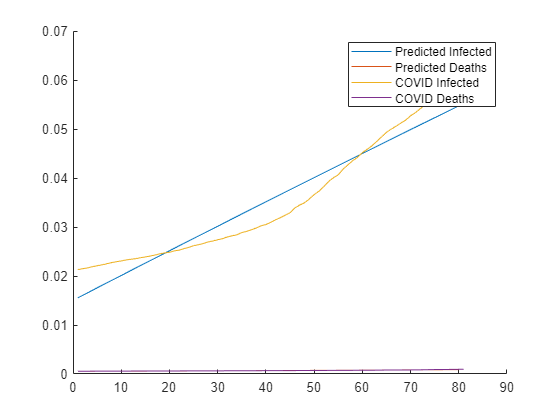

k_infections = x(1);
k_fatality = x(2);
k_recover = x(3);
disp


x0 = x(4:7);

A = [1-k_infections 0 0 0; 
    k_infections 1-k_recover-k_fatality 0 0; 
    0 k_recover 1 0; 
    0 k_fatality 0 1];
B = zeros(4,1);
sys_sir_base = ss(A,B,eye(4),zeros(4,1),1);
y = lsim(sys_sir_base,zeros(t,1),linspace(0,t-1,t),x0);

figure;
hold on
plot(y(:,2));
plot(y(:,4));
plot(coviddata);
legend('Predicted Infected','Predicted Deaths','COVID Infected','COVID Deaths');
hold off

% plot(Y);
% legend('S','L','I','R','D');
% xlabel('Time')

% Y_fit = siroutput_full(x,t);
% 
% figure(1);

% Make some plots that illustrate your findings.
% TO ADD